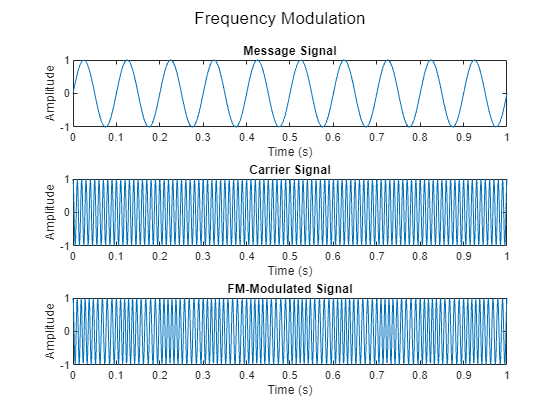

%Parameters
Fs=1000;
t=0:1/Fs:1;
Fc=100;
Fm=10;
Am=1;
Ac=1;
kf = 10;     % Frequency sensitivity (modulation index)

% Message signal
m = Am*sin(2*pi*Fm*t);  

% Carrier signal
c = Ac*cos(2*pi*Fc*t); 

% Frequency modulation
y = Ac*cos(2*pi*Fc*t + 2*pi*kf*cumsum(m)/Fs); 

% Plotting
figure;

subplot(3,1,1);
plot(t, m);
title('Message Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, c);
title('Carrier Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(t, y);
title('FM-Modulated Signal');
xlabel('Time (s)');
ylabel('Amplitude');

sgtitle('Frequency Modulation');